IAE = 2.4707			P = 32		I = 18		D = 10
IAE = 8.7164			P = 13.4276		I = 26.188		D = 13.8199
IAE = 0.12028			P = 4.8694		I = 21.4469		D = 0.034288
IAE = 5.1571			P = 39.915		I = 9.8625		D = 17.4347
IAE = 2.8391			P = 19.8325		I = 16.5702		D = 8.7971
IAE = 23.2657			P = 4.9971		I = 2.4777		D = 9.3211
IAE = 7.2532			P = 10.4222		I = 7.5942		D = 8.6653
IAE = 3.3009			P = 39.1057		I = 28.6575		D = 19.0794
IAE = 2.7112			P = 30.4204		I = 20.6718		D = 11.7043
IAE = 3.2807			P = 50.3215		I = 9.7104		D = 13.4508
IAE = 2.0848			P = 47.9404		I = 28.6542		D = 12.9345
IAE = 3.266			P = 50.477		I = 12.0682		D = 13.8005
IAE = 11.2318			P = 10.6884		I = 0.84838		D = 13.3113
IAE = 0.66728			P = 42.6833		I = 0.19675		D = 4.1895
IAE = 1.7533			P = 61.0118		I = 5.2756		D = 10.3548
IAE = 2.1025			P = 39.8849		I = 26.2837		D = 11.515
IAE = 5.0116			P = 37.5188		I = 6.8602		D = 15.5808
IAE = 1.7841			P = 62.0429		I = 32.1314		D = 12.6963
IAE = 2.9753			P = 40.5507		I = 1.4303		D = 19.4494
IAE = 3.8801			P = 17

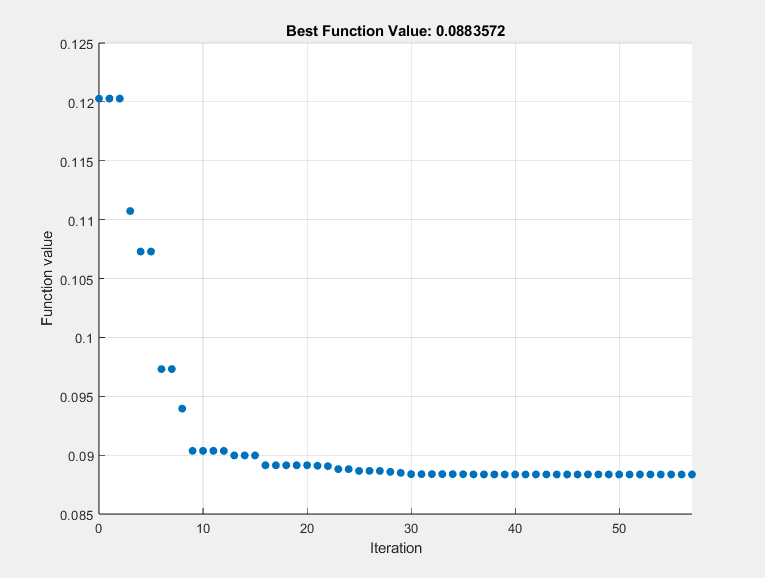

% Set nondefault solver options
options3 = optimoptions("particleswarm","InitialPoints",K_start,...
    "InertiaRange",Inertia_range,"SelfAdjustmentWeight",2.8,...
    "SocialAdjustmentWeight",1.3,"MaxIterations",100,"Display","iter",...
    "PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options3);


% Clear variables
clearvars options3